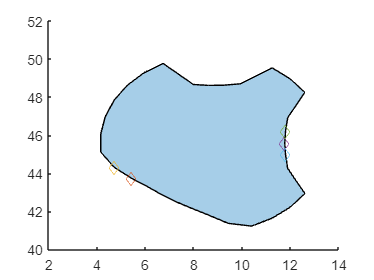

figure
hold on
px = bots(1).verts_unc(1,:);
py = bots(1).verts_unc(2,:);
plot(polyshape(px,py))
plot(px(19),py(19),'d')
plot(px(18),py(18),'d')
plot(px(1),py(1),'d')
plot(px(2),py(2),'d')
plot(px(end),py(end),'d')
hold off

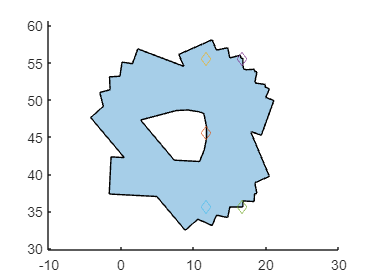


n_convI = convex_verts(bots(1).verts_unc);
rads = bots(1).polar_points(1,:);
angles = bots(1).polar_points(2,:);
poly1 = polyshape(bots(1).verts_unc(1,:),bots(1).verts_unc(2,:));
start_pt = bots(1).pos_est + rads(n_convI).*[cos(angles(n_convI));sin(angles(n_convI))];
pt1 = start_pt + 2*bots(1).rs*[cos(angles(n_convI) + pi/2);sin(angles(n_convI) + pi/2)];
pt2 = pt1 + bots(1).rs*[cos(angles(n_convI));sin(angles(n_convI))];
pt4 = start_pt + 2*bots(1).rs*[cos(angles(n_convI) - pi/2);sin(angles(n_convI) - pi/2)];
pt3 = pt4 + bots(1).rs*[cos(angles(n_convI));sin(angles(n_convI))];

for j=1:length(n_convI)
    cell_corr_verts = [pt1(:,j),pt2(:,j),pt3(:,j),pt4(:,j)];
    cell_correction{j} = polyshape(cell_corr_verts(1,:),cell_corr_verts(2,:));
end
cell_mat = repmat(polyshape, 1, length(cell_correction));
for k = 1:length(cell_mat)
    cell_mat(k) = cell_correction{k} ;
end
% inter = intersect(poly1,cell_correction);
to_del = union(cell_mat);
safety_set = subtract(poly1,to_del);
% bots(1).verts_unc = safety_set.Vertices';
bots(1).verts_zi = safety_set.Vertices';
figure
hold on
plot(to_del)
plot(start_pt(1),start_pt(2),'d')
plot(pt1(1),pt1(2),'d')
plot(pt2(1),pt2(2),'d')
plot(pt3(1),pt3(2),'d')
plot(pt4(1),pt4(2),'d')
hold off

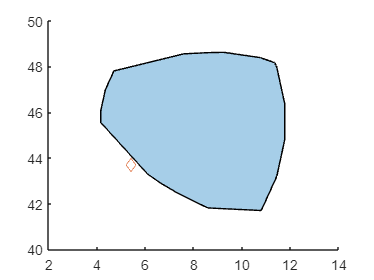

figure
hold on
plot(safety_set)
plot(bots(1).verts_unc(1,19),bots(1).verts_unc(2,19),'d')
hold off 

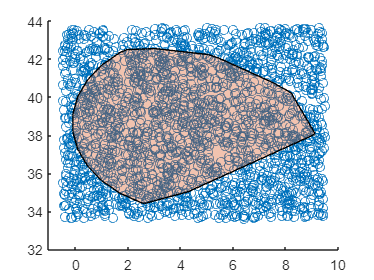

polii = polyshape(a(1,:),a(2,:));

samples = 2000;
int_size = 10;
point_in = bots(2).pos_est;
xq = int_size.* rand(samples,1)+point_in(1,1)-int_size/2;
yq = int_size.* rand(samples,1)+point_in(2,1)-int_size/2;
[in,on] = inpolygon(xq,yq,a(1,:),a(2,:));
plgn = polyshape(a(1,:),a(2,:));

figure
hold on
scatter(xq,yq);
plot(polii)
hold off

px = bots(1).verts_unc(1,:);
py = bots(1).verts_unc(2,:);
pxc = bots(1).verts_zi(1,:);
pyc = bots(1).verts_zi(2,:);

ind_pt = bots(1).indexconc;
interest_pt = [px(ind_pt);py(ind_pt)]';

figure, clf
hold on
xlim([34 44])
ylim([15 27])
plot(interest_pt(:,1),interest_pt(:,2),'o','MarkerFaceColor', 'b')
plot(all_obs,'FaceColor','black')
plot(polyshape(px,py))
legend('concave points','Location','northwest')
hold off


figure, clf
hold on
xlim([34 44])
ylim([15 27])
plot(interest_pt(:,1),interest_pt(:,2),'o','MarkerFaceColor', 'b')
plot(all_obs,'FaceColor','black')
plot(polyshape(pxc,pyc))
legend('concave points','Location','northwest')
hold off


pt1 = [42.6791, 19.6979];

figure, clf
hold on
xlim([34 44])
ylim([15 27])
plot(interest_pt(:,1),interest_pt(:,2),'o','MarkerFaceColor', 'b')
plot(all_obs,'FaceColor','black')
plot(polyshape(pxc,pyc))
legend('concave points','Location','northwest')
hold off

px = bots(1).verts_unc(1,:);
py = bots(1).verts_unc(2,:);

figure(3), clf
hold on
plot(px(5),py(5),'o','MarkerFaceColor', 'b')
plot(polyshape(px,py))
legend('concave points','Location','northwest')
hold off